cosine_matrix = [0.3536 0.3536 0.3536 0.3536 0.3536 0.3536 0.3536 0.3536;
    0.4904 0.4157 0.2778 0.0975 -0.0975 -0.2778 -0.4157 -0.4904;
    0.4619 0.1913 -0.1913 -0.4619 -0.4619 -0.1913 0.1913 0.4619;
    0.4157 -0.0975 -0.4904 -0.2778 0.2778 0.4904 0.0975 -0.4157;
    0.3536 -0.3536 -0.3536 0.3536 0.3536 -0.3536 -0.3536 0.3536;
    0.2778 -0.4904 0.0975 0.4157 -0.4157 -0.0975 0.4904 -0.2778;
    0.1913 -0.4619 0.4619 -0.1913 -0.1913 0.4619 -0.4619 0.1913;
    0.0975 -0.2778 0.4157 -0.4904 0.4904 -0.4157 0.2778 -0.0975;
    ];


quantization = [16 11 10 16 24 40 51 61;
                12 12 14 19 26 58 60 55;
                14 13 16 24  40 57 69 56;
                14 17 22 29 51 87 80 62;
                18 22 37 56 68 109 103 77;
                24 35 55 64 81 104 113 92;
                49 64 78 87 103 121 120 101;
                72 92 95 98 112 100 103 99;];


quantization = quantization* 20;



i = 1;
j = 1;



while i <= number_of_vertical_blocks
    j = 1;
    while j<=number_of_horizontal_blocks
       restored1(8*i-7:8*i,8*j-7:8*j)  = restored1(8*i-7:8*i,8*j-7:8*j).*quantization;
       restored1(8*i-7:8*i,8*j-7:8*j) = (cosine_matrix' *  restored1(8*i-7:8*i,8*j-7:8*j) * cosine_matrix) + 128;
       j = j+1;
    end
    i = i+1;
end





i = 1;
j = 1;



while i <= number_of_vertical_blocks
    j = 1;
    while j<=number_of_horizontal_blocks
       restored2(8*i-7:8*i,8*j-7:8*j)  = restored2(8*i-7:8*i,8*j-7:8*j).*quantization;
       restored2(8*i-7:8*i,8*j-7:8*j) = (cosine_matrix' *  restored2(8*i-7:8*i,8*j-7:8*j) * cosine_matrix) + 128;
       j = j+1;
    end
    i = i+1;
end





i = 1;
j = 1;



while i <= number_of_vertical_blocks
    j = 1;
    while j<=number_of_horizontal_blocks
       restored3(8*i-7:8*i,8*j-7:8*j)  = restored3(8*i-7:8*i,8*j-7:8*j).*quantization;
       restored3(8*i-7:8*i,8*j-7:8*j) = (cosine_matrix' *  restored3(8*i-7:8*i,8*j-7:8*j) * cosine_matrix) + 128;
       j = j+1;
    end
    i = i+1;
end


restored = zeros(rows,columns,3);

restored(:,:,1) = restored1

restored = restored(:,:,1) =

  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316


restored(:,:,2) = restored2

restored = restored(:,:,1) =

  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316


restored(:,:,3) = restored3

restored = restored(:,:,1) =

  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  208.0211  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316  248.0316

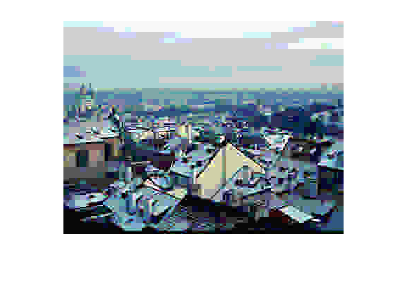




restored = uint8(restored);



imshow(restored)